# *E.coli *(iJO1366) "Glycine and Serine Metabolism" Subsystem

Author: H. Scott Hinton, Utah State University

Reviewer:

## INTRODUCTION

The purpose of this tutorial is to review the basic structure and capabilities of the "Glycine and Serine Metabolism" subsystem of the iJO1366* E.coli* model.

## MATERIALS

This tutorial is based on the *Constraint-Based Reconstruction and Analysis* (COBRA) Toolbox [1,2]. To use this tutorial requires the 2016a or newer version of Matlab ([https://www.mathworks.com](https://www.mathworks.com)/) and the COBRA toolbox software that can be downloaded from [https://opencobra.github.io/cobratoolbox/latest/index.html.](https://opencobra.github.io/cobratoolbox/latest/index.html.) The installation instructions and troubleshooting tips are also available on this website.

## **EQUIPMENT SETUP**

Initalize the COBRA toolbox.

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  (not installed).
 > Checking if remote can be reached ...  (unsuccessful - no internet connection).
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.


 > Try running
   >> TranslateSBML('C:\Users\hinton\cobratoolbox\test\models\Ec_iAF1260_flux1.xml');
   in order to debug.
 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [-*--] GUROBI_PATH: C:\gurobi702\win64\matlab
   - [----] TOMLAB_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ... Done.
 > Setting default solvers ... Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver int

Select the optimizer solver.

% changeCobraSolver('glpk','all');
changeCobraSolver('gurobi7','all');

 > CBT_LP_SOLVER has been set to gurobi.
 > CBT_MILP_SOLVER has been set to gurobi.
 > CBT_QP_SOLVER has been set to gurobi.
 > CBT_MIQP_SOLVER has been set to gurobi.
 > CBT_NLP_SOLVER has been set to gurobi.


% changeCobraSolver('tomlab_cplex','all');
% changeCobraSolver('gurobi6','all');

Load the *E.coli *iJO1366 model.

load('iJO1366.mat');
saved_model = iJO1366;
model = saved_model;

## PROCEDURE

## **1.** **Glycine and ****Serine ****M****etabolism**

The purpose of this tutorial is to identify and review the structure and capabilities of the "Glycine and Serine Metabolism" subsystem of the *E.coli* iJO1366 model. This will begin with an overview of the complete subsystem. This overview will be followed by more detailed descriptions of the individaul glycine and L-serine biosynthesis pathways. It will conclude with a simulation that shows the maximum flux that each these amino acids can produce in an oxidative range from anaerobic to aerobic conditions.

The reactions associated with the "Glycine and Serine Metabolism" subsystem can be extracted from the model as shown below.

model = saved_model;
glycineSerineSubSystems = {'Glycine and Serine Metabolism'};
glycineSerineReactions = model.rxns(ismember(model.subSystems,glycineSerineSubSystems));
[tmp,glycineSerine_rxnID] = ismember(glycineSerineReactions,model.rxns);
reactionNames = model.rxnNames(glycineSerine_rxnID);
reactionFormulas = printRxnFormula(model,glycineSerineReactions,0);
T = table(reactionNames,reactionFormulas,'RowNames',glycineSerineReactions)

T = 14×2 table
                               reactionNames                                         reactionFormulas                    
               ______________________________________________    ________________________________________________________

    DSERDHr    'D-serine dehydrogenase'                          'nadp_c + ser__D_c  <=> 2amsa_c + h_c + nadph_c '       
    GHMT2r     'Glycine hydroxymethyltransferase, reversible'    'ser__L_c + thf_c  <=> gly_c + h2o_c + mlthf_c '        
    GLYAT      'Glycine C-acetyltransferase'                     'accoa_c + gly_c  <=> 2aobut_c + coa_c '                
    GLYCK2     'Glycerate kinase'                                'atp_c + glyc__R_c  -> 2pg_c + adp_c + h_c '            
    LSERDHr    'L-serine dehydrogenase'                          'nadp_c + ser__L_c  <=> 2amsa_c + 

The connectivity between these reactions can be visualized through an Escher [3] map of this  "Glycine and Serine Metabolism" subsystem as shown below (Glycine_Serine_Subsystem.json).

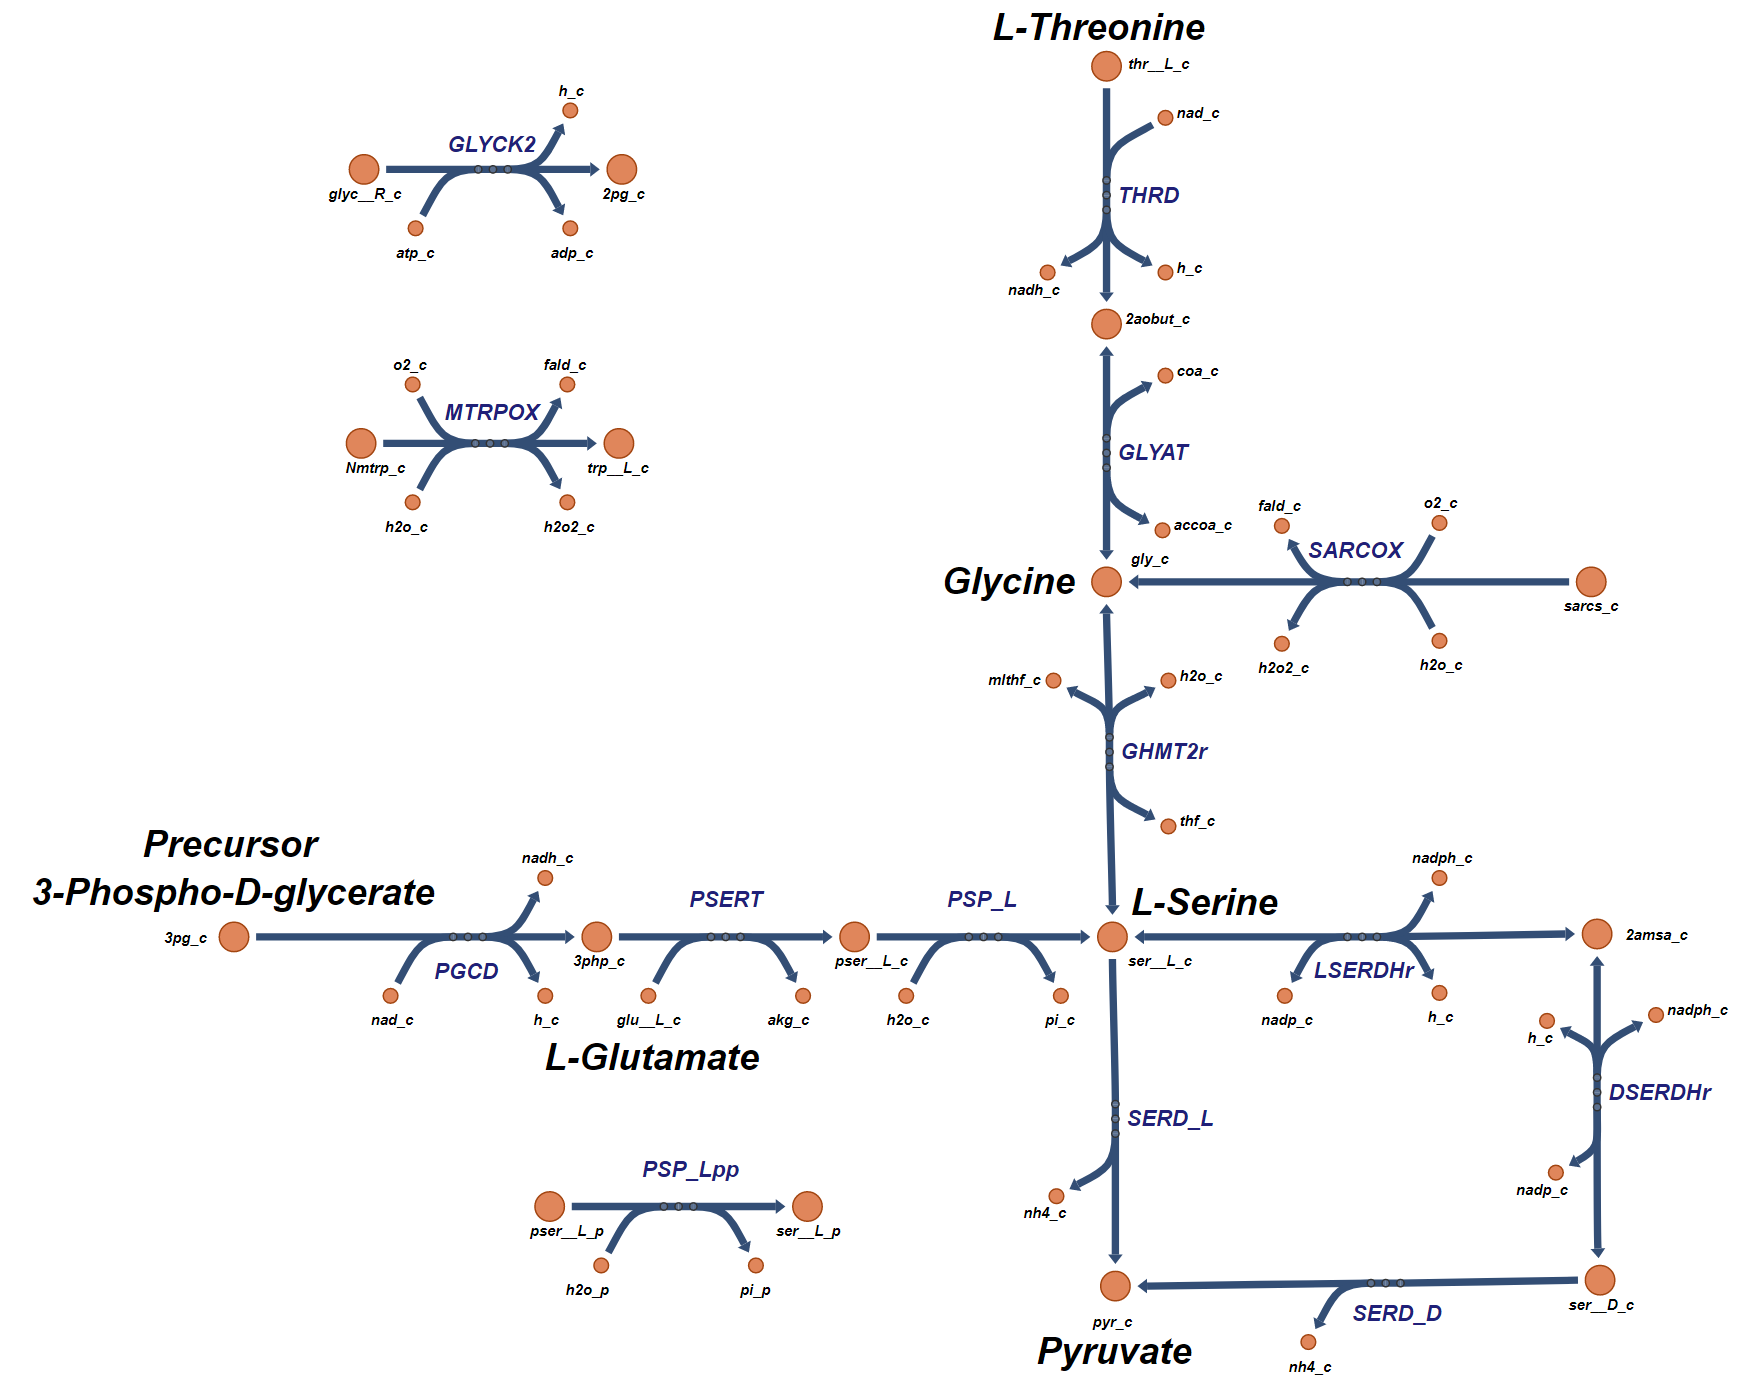

**Figure 1. **Network map of the "Glycine and Serine Metabolism" subsystem.

This subsystem begins with the precursor 3-Phospho-D-glycerate ('3pg_c') and a shared path that includes 'PGCD', 'PSERT', and 'PSP_L'. This shared path results in the production of L-serine. L-serine can also be produced through a short pathway ('DESRDHr' and 'LSERDHr') that converts D-serine ('ser__D_c') into L-serine. In addition, L-serine can be produced from glycine through the bidrectional  'GHMT2r' reaction that can balance the ratio of glycine to L-serine. 

Glycine can be produced from L-serine or can be produced from L-threonine through two reactions 'THRD' and 'GLYAT' or from sarcosine ('sarcs_c') through the reaction 'SARCOX'.

There are also three other reactions included in the "Glycine and Serine Metabolism" subsystem, they include 'GLYCK2', 'MTRPOX', and 'PSP_Lpp'.

Below is an Escher [3] figure of the "Glycine and Serine Metabolism" subsystem in an aerobic condition using "Aerobic_Reaction_Flux.csv" as the data file.

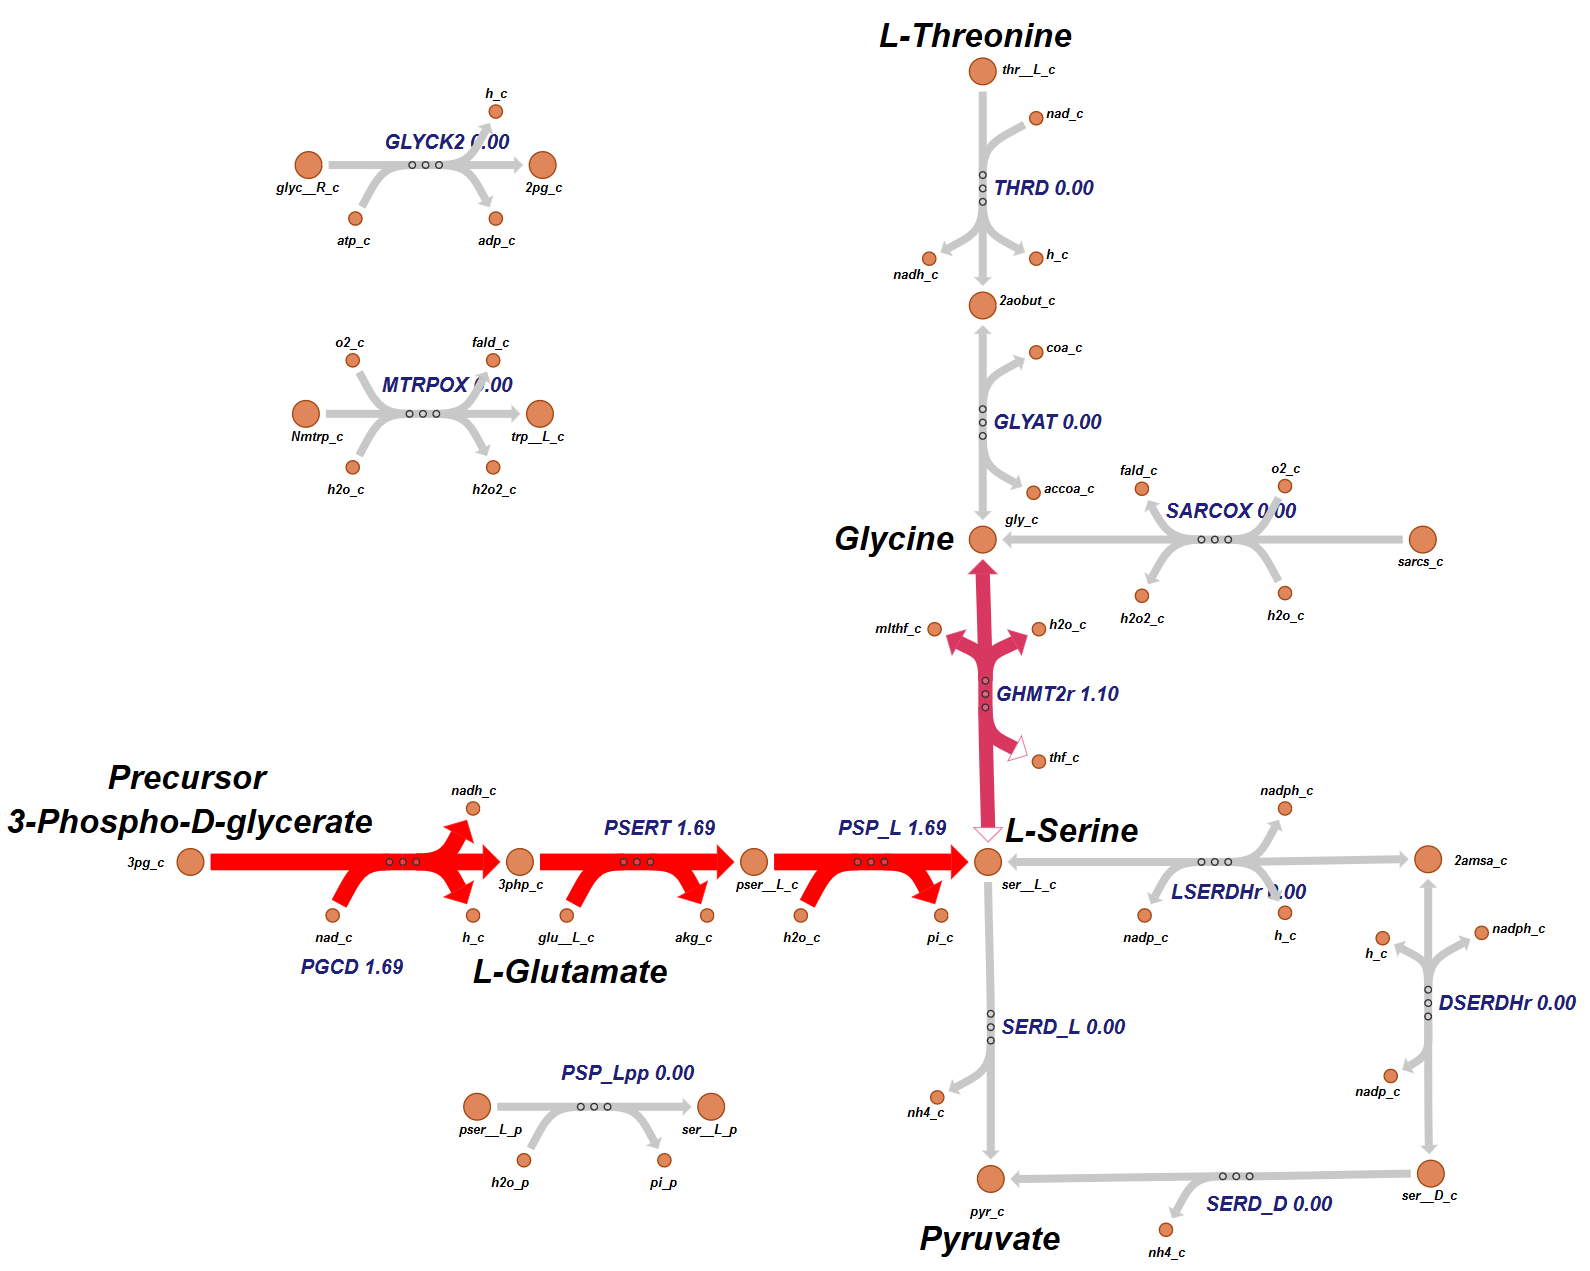

**Figure 2.** The flux flowing through the "Glycine and Serine Metabolism" subsystem under aerobic conditions.

In this figure we can see that the a flux from precursor '3pg_c' flows through the reactions ('PGCD', 'PSERT', and 'PSP_L') associated with the primary pathways to produce L-serine at a flux rate of 1.69 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$. A portion of this flux, 1.10 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$, is redirected to through the reaction 'GHMT2r' to produce glycine.

Now let's explore the details of the biosynthesis pathways for glycine and L-serine. 

**L-Serine Biosynthesis**

Let's begin by identifying the major producers of L-serine using "surfNet". 

surfNet(model, 'ser__L_c')


Met #885  ser__L_c, L-Serine, C3H7NO3
Consuming reactions:
#7  BIOMASS_Ec_iJO1366_WT_53p95M  E. coli biomass objective function (iJO1366) - WT - with 53.95 GAM estimate  
  0.000223 10fthf_c + 0.000223 2dmmql8_c + 2.5e-05 2fe2s_c + 
  0.000248 4fe4s_c + 0.000223 5mthf_c + 0.000279 accoa_c + 0.000223 adocbl_c 
  + 0.49915 ala__L_c + 0.000223 

From these results, combined with figure 1, we can see that there are five reactions, that based on their reaction formula, directly produce L-serine, they include 'DHBSH','GPDDA3', 'PSP_L', 'SERt2rpp', and 'SERt4pp'. The last two reactions ('SERt2rpp', and 'SERt4pp') on this list are transporters that move diffused L-serine from the periplasm to the cytoplasm. The third reaction ( 'PSP_L') on the list is the final reaction of the primary pathway ('PGCD', 'PSERT', and 'PSP_L'). The first two reactions ('DHBSH' and 'GPDDA3',) are not included in the "Glycine and Serine Metabolism" subsystem but provide alternate sources of L-serine. The first reaction, 'DHBSH', is part of the "Cofactor and Prosthetic Group Biosynthesis" subsystem and is part of the enterochelin biosytnthesis pathway. The second reaction, 'GPDDA3', is part of the "Glycerophospholipid Metabolism" subsystem. There are also other reaction listed under the consuming reaction that are bidirectional and thus have the ability to also produce L-serine. These reactions include 'GHMT2r', 'LSERDHr', 'SERASr', and 'SERAT'. 

All these reaction are shown in the following Escher-based [3] figure. 

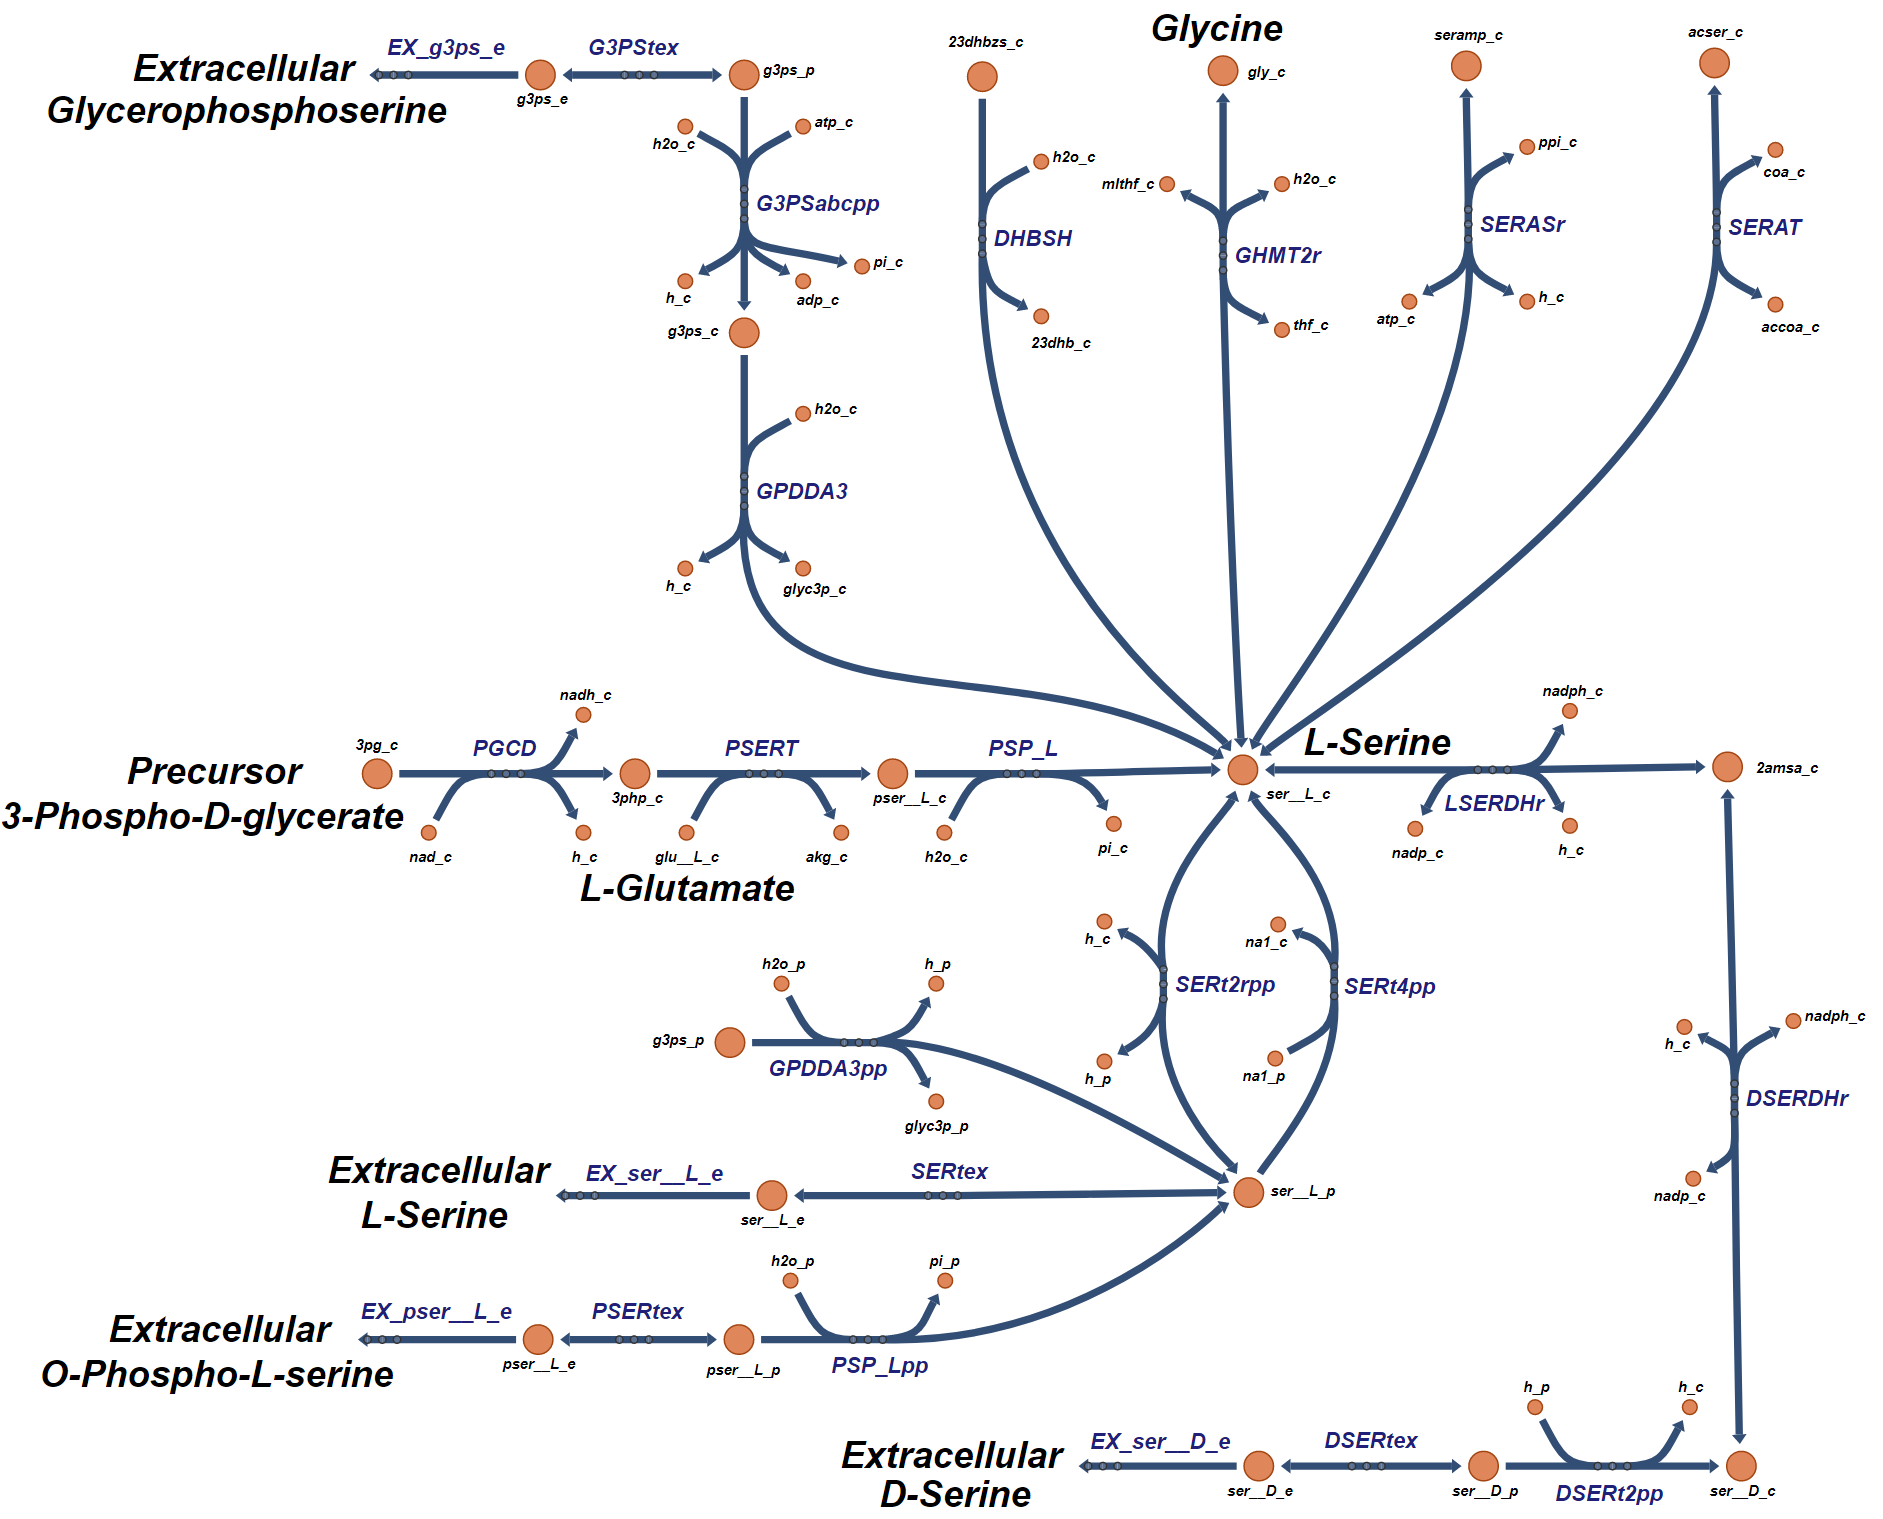

**Figure 3.** Biosynthesis pathways for the production of L-serine.

The primary pathway ('PGCD','PSERT', and 'PSP_L') begins with '3pg_c' and ends with L-serine. The second pathway ('GHMT2r') provides the converstion from glycine to L-serine. The third pathway ('DHBSH') is a reaction in the "enterochelin" biosynthesis pathway.The fourth pathway ('GPDDA3', 'G3PSabcpp, 'G3PStex',and 'EX_g3ps_e') are reactions in the "glycerophosphodiester phosphodiesterase" biosynthesis pathway. This pathway can be used as an alternate pathway for the creation of L-serine from extracellular glycerophosphoserine. The fifth pathway ('SERASr') is also a reaction in the "enterochelin" biosynthesis pathway. The sixth pathway ('SERAT') is a reaction in the L-cysteine biosyntesis pathway. The seventh pathway ('LSERDHr', 'DSERDHr', 'DSERt2pp', 'DSERtex', and 'EX_ser__D_e') are reactions in the pathway that converts the diffused D-serine ('ser__D_c') into L-serine. This also includes a pathway to extracellular D-serine. Finally, there are the transport reactions ('SERt2rpp', 'SERt4pp', and 'SERtex') that bring the L-serine from the proplasm into the cytoplasm. There are two pathways that lead to periplasmic L-serine. The first is standard diffusion ('SERtex' and 'EX_ser__L_e').  The second ('PSP_Lpp', 'PSERtex', and 'EX_pser__L_e') is the diffusion and conversion of O-Phospho-L-serine. There is one other reaction ('GPDDA3pp') that could create periplasmic L-serine, but it is a dead-end reaction, since there is no path to create it's substrate 'g3ps_p'.

Now let's explore the fluxes through thee L-serine pathways.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
serineReactions = transpose({'PGCD','PSERT','PSP_L','GHMT2r','GPDDA3','G3PSabcpp','G3PStex','EX_g3ps_e','DHBSH','SERASr','SERAT',...
    'LSERDHr','DSERDHr','DSERt2pp','DSERtex','EX_ser__D_e','SERt2rpp','SERt4pp','SERtex','EX_ser__L_e','PSP_Lpp','PSERtex','EX_pser__L_e'});
[tmp,serine_rxnID] = ismember(serineReactions,model.rxns);
printLabeledData(serineReactions, round(FBAsolution.x(serine_rxnID),3))

PGCD	1.688	
PSERT	1.688	
PSP_L	1.688	
GHMT2r	1.096	
GPDDA3	0	
G3PSabcpp	0	
G3PStex	0	
EX_g3ps_e	0	
DHBSH	0	
SERASr	-0	
SERAT	0.244	
LSERDHr	-0	
DSERDHr	0	
DSERt2pp	0	
DSERtex	0	
EX_ser__D_e	0	
SERt2rpp	-0.005	
SERt4pp	0.005	
SERtex	0	
EX_ser__L_e	0	
PSP_Lpp	0	
PSERtex	0	
EX_pser__L_e	0	


Note that the majority of the L-serine creating flux passes through the primary pathway. Part of that L-serine flux is diverted through 'GHMT2r' to Gycine. Another part of the L-serine flux is diverted through 'SERAT' to the L-cyseine biosynthesis pathway. It also looks like there could be a small loop invovling the transporters 'SERt2rpp' and SERt4pp'. Let's explore this with surfNet.

surfNet(model, 'ser__L_p',0,FBAsolution.x,1,1)


Met #1755  ser__L_p, L-Serine, C3H7NO3
Consuming reactions with non-zero fluxes :
#2347  SERt4pp  L-serine via sodium symport (periplasm)  (0.005113)
  na1_p + ser__L_p -> na1_c + ser__L_c  
Producing reactions with non-zero fluxes :
#2346  SERt2rpp  L-serine reversible transport via proton symport (periplasm)  (-0.005113)
  h_p + ser__L_p <=> h_c + ser__L_c  



Confirmed!

**Glycine Biosynthesis**

Let's begin by identifying the major producers of glycine using "surfNet".

surfNet(model, 'gly_c')


Met #551  gly_c, Glycine, C2H5NO2
Consuming reactions:
#7  BIOMASS_Ec_iJO1366_WT_53p95M  E. coli biomass objective function (iJO1366) - WT - with 53.95 GAM estimate  
  0.000223 10fthf_c + 0.000223 2dmmql8_c + 2.5e-05 2fe2s_c + 
  0.000248 4fe4s_c + 0.000223 5mthf_c + 0.000279 accoa_c + 0.000223 adocbl_c 
  + 0.49915 ala__L_c + 0.000223 

From these results, combined with figure 1, we can see that there are five reactions, that based on their reaction formula, directly produce glycine, they include 'AMPTASECG', 'AMPTASEPG', 'GHMT2r', 'GLYt2pp_copy1', 'GLYt2pp_copy2', 'GLYt4pp', 'SARCOX', 'THRA2i', and 'THRAi'. There are also other reactions listed under the consuming reaction that are bidirectional and thus have the ability to also produce L-serine. These reactions include 'GLYAT' and 'PRAGSr'. 

All these reactions, addition to some other supporting reactions, are shown in the following Escher-based [3] figure. 

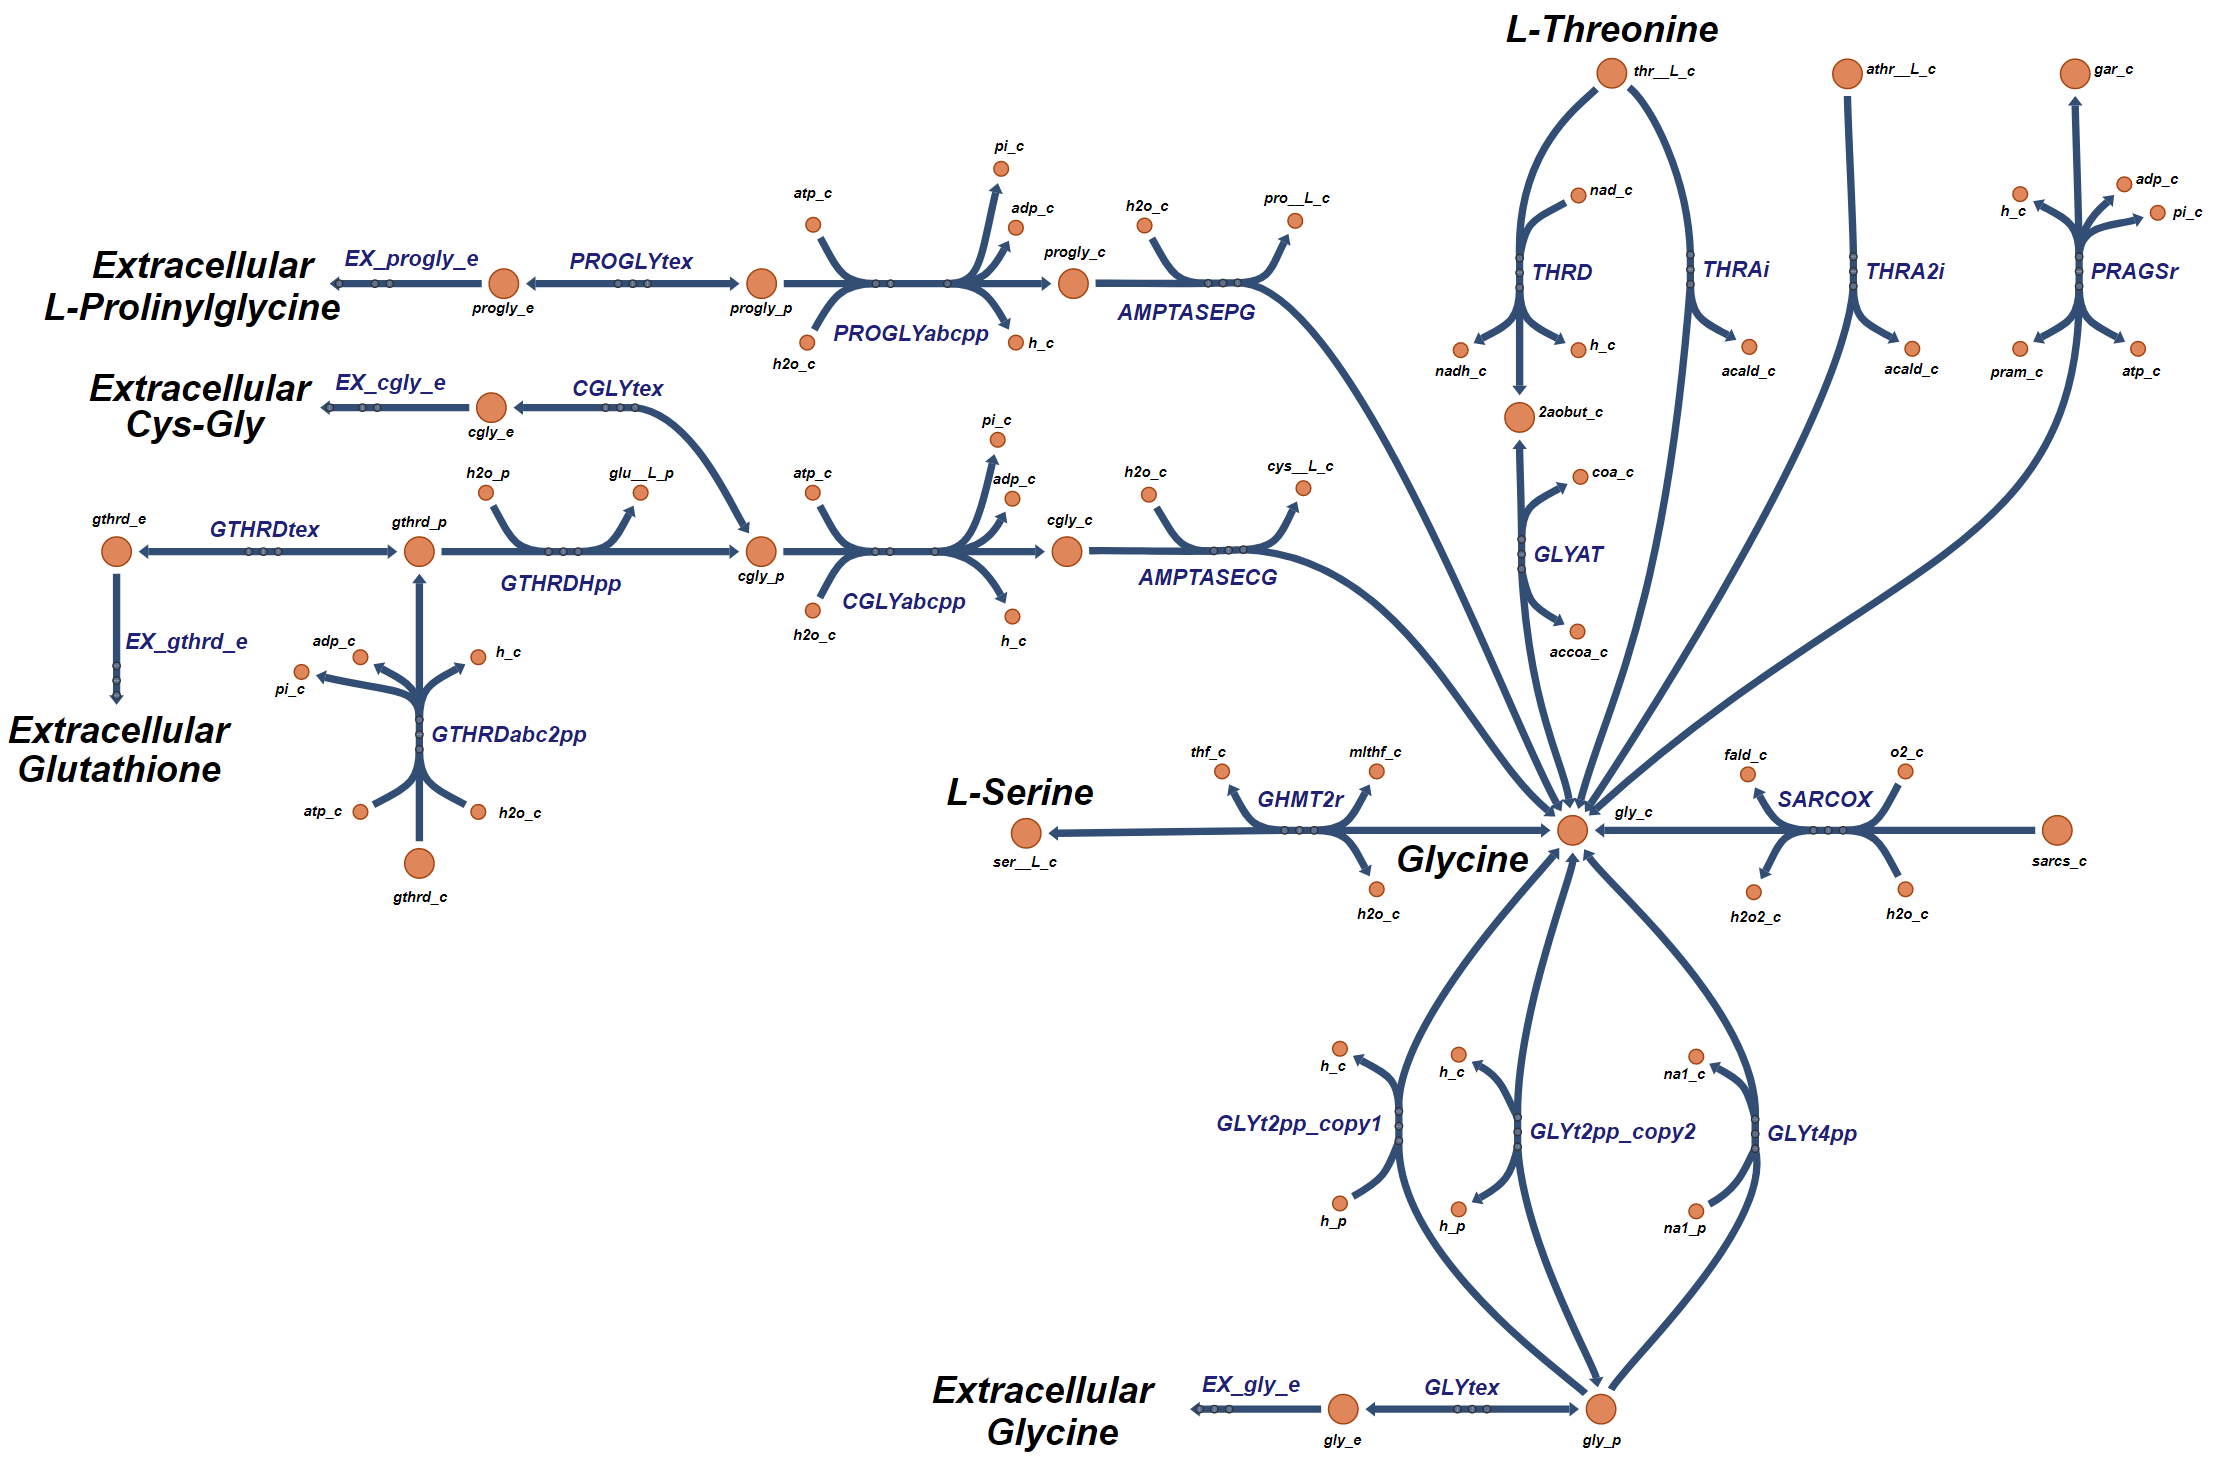

**Figure xx. **Biosynthesis reactions for the production of Glycine.

The primary Glycine biosynthesis pathway begins with L-serine which is converted to glycine through 'GHMT2r'.  A second pathway ('AMPTASECG') is associated with the breakdown of cyc-gly ('cgly_c') into L-cysteine and Glycine. A third pathway ('AMPTASEPG') is associated with the breakdown of xxxx ('progly_c') into L-proline and Glycine. A fourth pathway ('THRA2i') is associated with the breakdown of L-threione. The fifth pathway ('PRAGSr') is part of the Purine biosyntheis pathway. The sixth pathway allows the conversion sarcosine to Glycine. There are also two pathways ('THRD', 'GLYAT', and 'THRAi') that can be used to convert L-threione to Glycine. Finally, there are three different transporters ('GLYt2pp_copy1', 'GLYt2pp_copy2', and 'GLYt4pp' ) that can bring diffused Glycine from the periplasmic space into the cytoplasm.

Now let's look at the flux values of these pathways in an aerobic environment.

surfNet(model, 'gly_c',0,FBAsolution.x,1,1)


Met #551  gly_c, Glycine, C2H5NO2
Consuming reactions with non-zero fluxes :
#8  BIOMASS_Ec_iJO1366_core_53p95M  E. coli biomass objective function (iJO1366) - core - with 53.95 GAM estimate  (0.982372)
  0.000223 10fthf_c + 2.6e-05 2fe2s_c + 0.000223 2ohph_c + 0.00026 4fe4s_c 
  + 0.51369 ala__L_c + 0.000223 amet_c + 0.29579 arg__L_c + 0.24105 asn__L_c 
  + 0.24105 asp__L_c + 54

In this case, note that only the primary pathway ('GHMT2r') is active and producing Glycine. We can aslo see that, in addition to the biomass function, there are only two pathways that are activily consuming Glycine, 'GLYCL' and 'PRAGSr'

**L-Serine Biosynthesis**

What are the major producers of L-serine?

surfNet(model, 'ser__L_c')


Met #885  ser__L_c, L-Serine, C3H7NO3
Consuming reactions:
#7  BIOMASS_Ec_iJO1366_WT_53p95M  E. coli biomass objective function (iJO1366) - WT - with 53.95 GAM estimate  
  0.000223 10fthf_c + 0.000223 2dmmql8_c + 2.5e-05 2fe2s_c + 
  0.000248 4fe4s_c + 0.000223 5mthf_c + 0.000279 accoa_c + 0.000223 adocbl_c 
  + 0.49915 ala__L_c + 0.000223 

A figure showing the reactons that can be used to produce L-serine is given below.

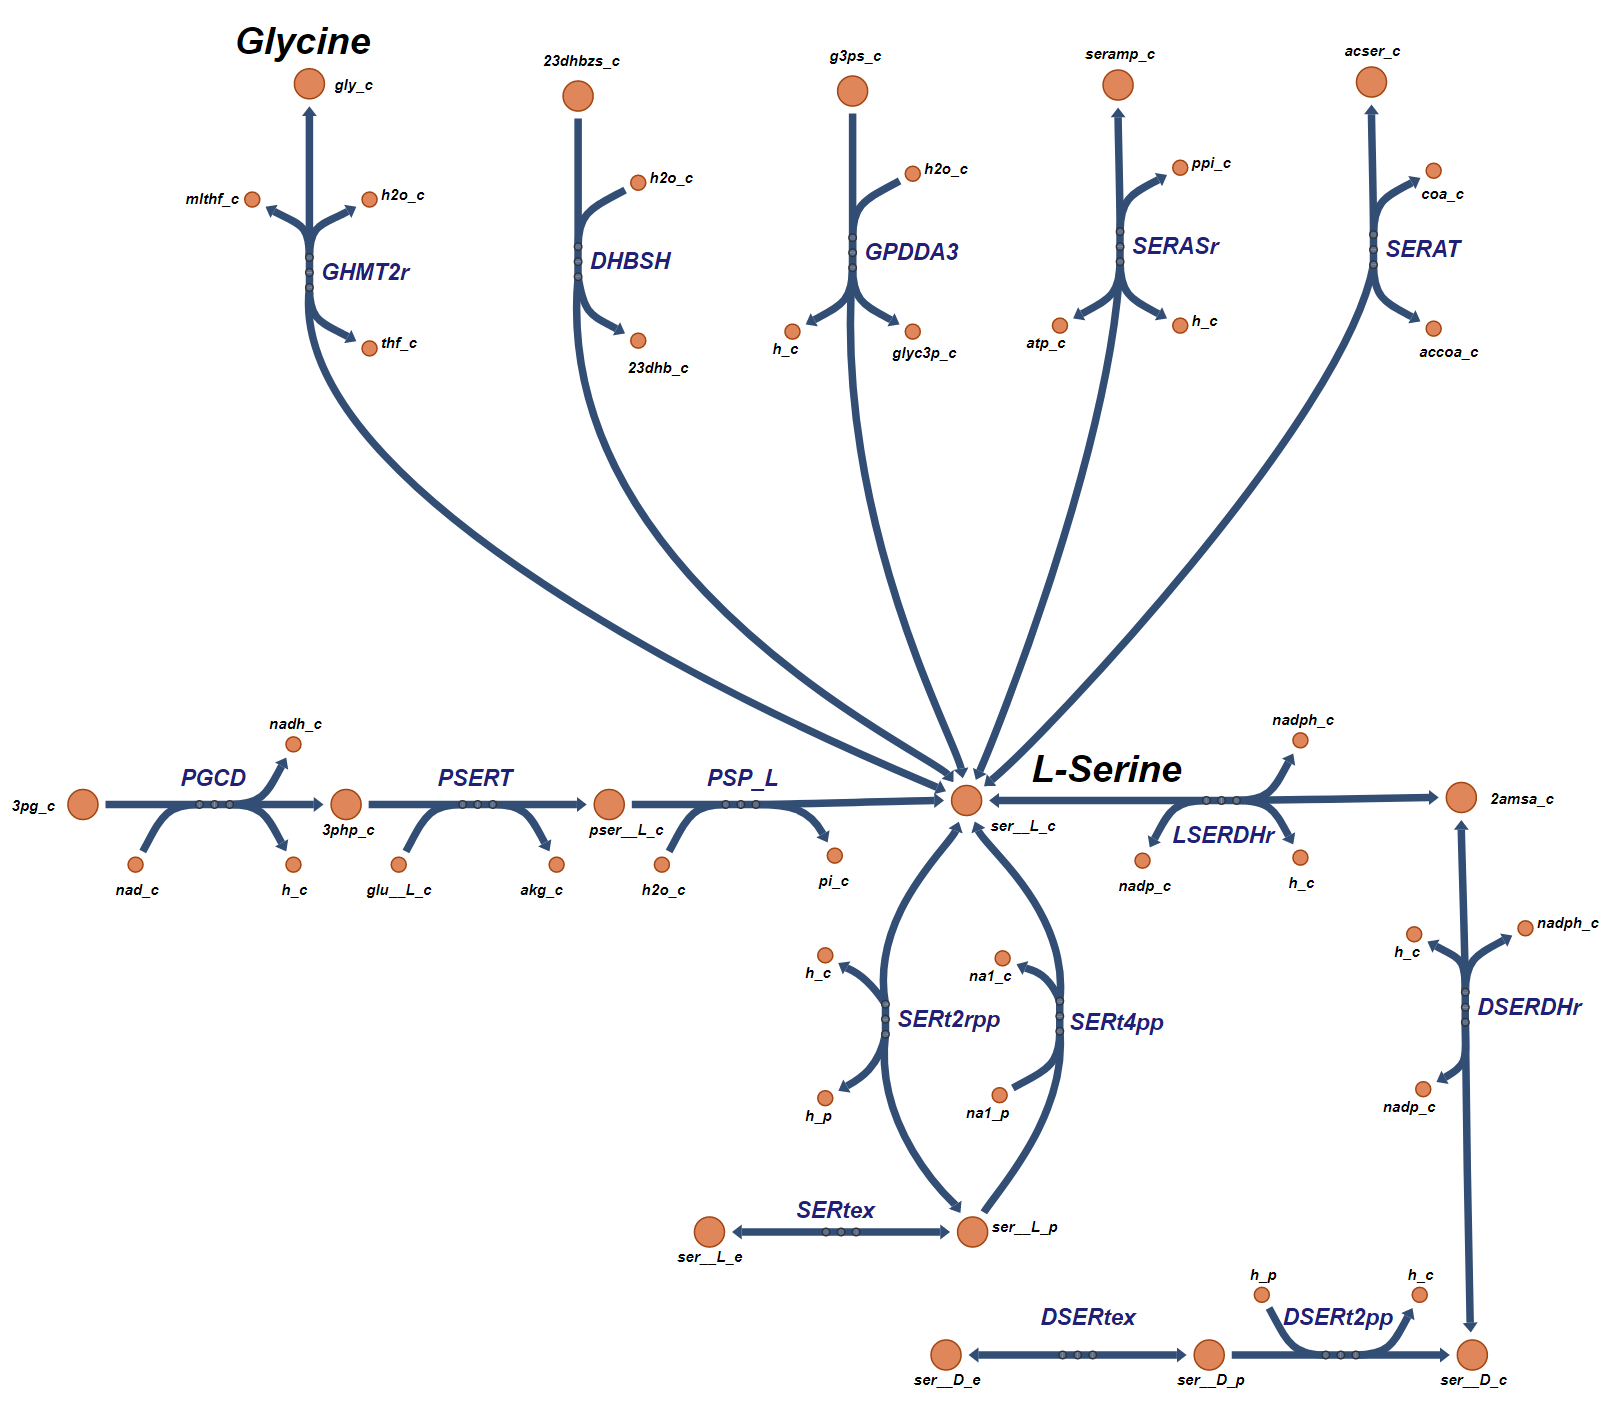

**Figure xx.** Biosynthesis pathways for the production of L-serine.

The primary pathway ('PGCD','PSERT', and 'PSP_L') begins with '3pg_c' and ends with L-serine. The second pathway ('GHMT2r') provides the converstion from Glycine to L-serine. The third pathway ('DHBSH') is a reaction in the "enterochelin" biosynthesis pathway.The fourth pathway ('GPDDA3') is a reaction in the "glycerophosphodiester phosphodiesterase" biosynthesis pathway. The fifth pathway ('SERASr') is also a reaction in the "enterochelin" biosynthesis pathway. The sixth pathway ('SERAT') is a reaction in the L-cysteine biosyntesis pathway. The seventh pathway ('LSERDHr', 'DSERDHr', 'DSERt2pp', and 'DSERtex') are reactions in the pathway that converts the diffused D-serine ('ser__D_c') into L-serine. Finally, there are the trasport reactions ('SERt2rpp', 'SERt4pp', and 'SERtex') that bring the diffused L-serine from the proplasm into the cytoplasm.

Now let's explore the fluxes through this network.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
serineReactions = transpose({'PGCD','PSERT','PSP_L','GHMT2r','DHBSH','GPDDA3','SERASr','SERAT',...
    'LSERDHr', 'DSERDHr', 'DSERt2pp','DSERtex','SERt2rpp','SERt4pp','SERtex'});
[tmp,serine_rxnID] = ismember(serineReactions,model.rxns);
printLabeledData(serineReactions, round(FBAsolution.x(serine_rxnID),3))

PGCD	1.688	
PSERT	1.688	
PSP_L	1.688	
GHMT2r	1.096	
DHBSH	0	
GPDDA3	0	
SERASr	-0	
SERAT	0.244	
LSERDHr	-0	
DSERDHr	0	
DSERt2pp	0	
DSERtex	0	
SERt2rpp	-0.005	
SERt4pp	0.005	
SERtex	0	


Note that the majority of the L-serine creating flux passes through the primary pathway. Part of that L-serine flux is diverted through 'GHMT2r' to Gycine. Another part of the L-serine flux is diverted through 'SERAT' to the Lcyseine biosynthesis pathway. It also looks like there could be a small loop invovling the transporters 'SERt2rpp' and SERt4pp'. Let's explore this with surfNet.

surfNet(model, 'ser__L_p',0,FBAsolution.x,1,1)


Met #1755  ser__L_p, L-Serine, C3H7NO3
Consuming reactions with non-zero fluxes :
#2347  SERt4pp  L-serine via sodium symport (periplasm)  (0.005113)
  na1_p + ser__L_p -> na1_c + ser__L_c  
Producing reactions with non-zero fluxes :
#2346  SERt2rpp  L-serine reversible transport via proton symport (periplasm)  (-0.005113)
  h_p + ser__L_p <=> h_c + ser__L_c  



Confirmed!

## 5. Conclusion

This wraps up the tutorial on the *E.coli* core model. It has attempted to show how the COBRA toolbox can be used to explore a genome-scale metabolic network reconstruction using the core model as an example. Now with this beginning skill set you can start exploring the larger and more accurate network reconstructions!

## References

- Palsson, B. (2015). Systems biology : constraint-based reconstruction and analysis. Cambridge, United Kingdom, Cambridge University Press.

- Palsson, B. (2006). Systems biology : properties of reconstructed networks. Cambridge ; New York, Cambridge University Press.

- Orth, Fleming, and Palsson (2010), *EcoSal Chapter 10.2.1 - Reconstruction and Use of Microbial Metabolic Networks: the Core* Escherichia coli *Metabolic Model as an Educational Guide*  - [http://www.asmscience.org/content/journal/ecosalplus/10.1128/ecosalplus.10.2.1#backarticlefulltext](http://www.asmscience.org/content/journal/ecosalplus/10.1128/ecosalplus.10.2.1#backarticlefulltext)

- Becker, S. et al., ["Quantitative prediction of cellular metabolism with constraint-based models: The COBRA Toolbox"](http://www.nature.com/nprot/journal/v2/n3/full/nprot.2007.99.html), *Nat. Protoc* **2**, 727-738 (2007). 

- Schellenberger J, Que R, Fleming RMT, Thiele I, Orth JD, Feist AM, Zielinski DC, Bordbar A, Lewis NE, Rahmanian S et al., [Quantitative prediction of cellular metabolism with constraint-based models: the COBRA Toolbox v2.0](http://www.ncbi.nlm.nih.gov/pubmed/21886097?dopt=Abstract) *Nat Protoc* **6**(9):1290-307 (2011).

- Feist, A. M., Herrgard, M. J., Thiele, I., Reed , J . L., and Palsson, B. 0., (2009). Reconstruction of biochemical networks in microorganisms. Nat. Rev Microbiol 7 : 129-143. 

- Price, N. D., Papin, J . A., Schilling, C. H. , and Palsson, B. 0., (2003) Genome-scale microbial *in silico* models: the constraints-based approach. Trends Biotechnol 21:162-169.

- Orth, J. D., I. Thiele, et al. (2010). "What is flux balance analysis?" Nature biotechnology 28(3): 245-248. 

- Schellenberger, J., Park, J. O., Conrad, T. M., and Palsson, B. O., (2010) ["BiGG: a Biochemical Genetic and Genomic knowledgebase of large scale metabolic reconstructions"](http://www.biomedcentral.com/1471-2105/11/213), *BMC Bioinformatics*, **11**:213, (2010).

- King, Z.A., Lu, J., Draeger, A., Miller, P., Federowicz, S., Lerman, J.A., Palsson, B.O., Lewis, N.E., (2015)  ["BiGG models: A platform for integrating, standardizing and sharing genome-scale models"](http://nar.oxfordjournals.org/content/early/2015/10/15/nar.gkv1049.long), *Nucleic Acids Research* (2015)

- Schaechter, M., Ingraham, J. L., Neidhardt, F. C. (2006), "Microbe", ASM Press, Washington, D. C.

- Edwards, J. S. and B. O. Palsson (2000). "Robustness analysis of the Escherichia coli metabolic network." Biotechnology progress 16(6): 927-939.

- M. Schaechter et al, "Microbe", ASM Press, 2006, p.119.

- D. White, "The physiology and biochemistry of prokaryotes," 3rd edition, Oxford University Press, 2007.